# ChebyshevN

generate Chebyshev polynomial of degree $n$.

## Syntax

## Description

ChebyshevN generates a Chybyshev polynomial of degree $n$, where $x$ is vector of points in which will be calculated values of Chebyshev polynomial.

## Example

Plot first five Chebyshev polynomials

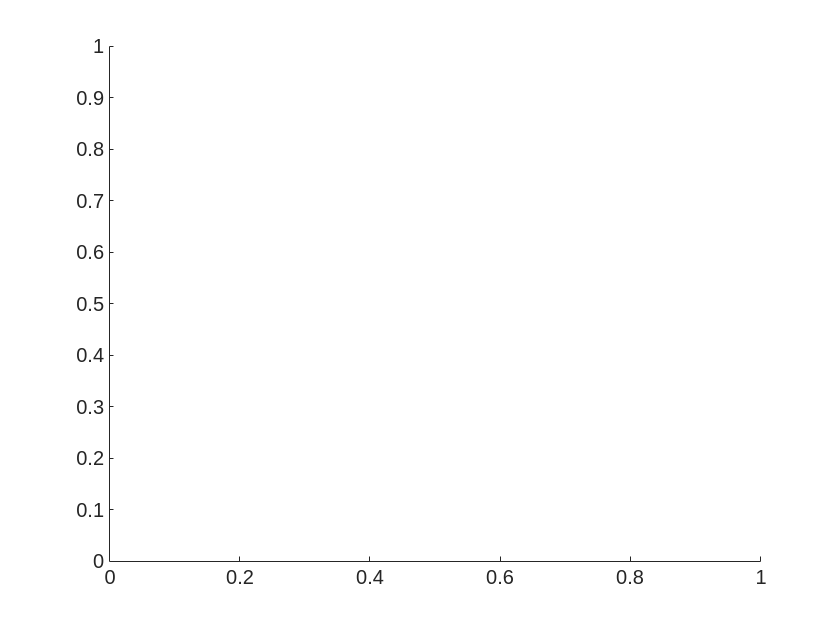

x = -1:0.01:1;
figure(1);
hold on;

n =9;
Che = ChebyshevN(n,x);

Unrecognized function or variable 'ChebyshevN'.

plot(x, Che);
grid on;
xlabel("x");
ylabel("Che(x)")

## Comparison with book

In book [Янке Е., Эмде Ф., Леш Ф. - "Специальные функции"] we can find equations for fist six xhebyshev polynomials ( $T_0$ to $T_5$):

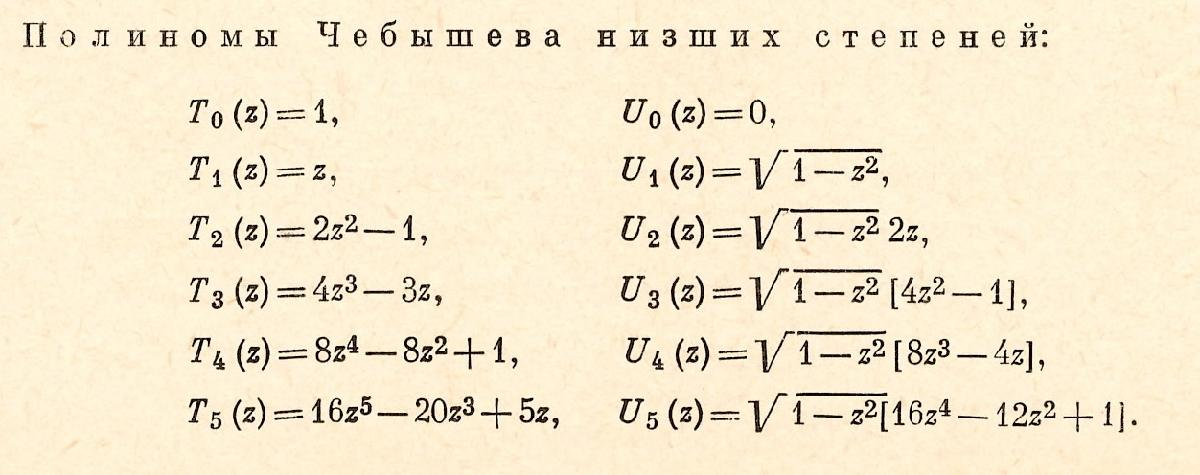

This script compares the first six Chebyshev polynomyals generated by function ChebyshevN wit polynomials from this book.

x = [0:0.01:1];
Chebook = zeros(6, length(x));
Chefce = Chebook;
Chebook(1,:) = ones(1,length(x));
Chebook(2,:) = x;
Chebook(3,:) = 2*x.^2 - 1;
Chebook(4,:) = 4*x.^3 - 3*x;
Chebook(5,:) = 8*x.^4 - 8*x.^2 + 1;
Chebook(6,:) = 16*x.^5 -20*x.^3 + 5*x;

for i = 0:5
    Chefce(i+1,:) = ChebyshevN(i, x);
end

diff = Chefce - Chebook; % compute difference betveen polynomials generated by function ChebyshevN and polynomials form book
AbsDiff = max(abs(diff'))' % find absolute maximum difference for all polynomials
% I hope you enjoyed this excercise!